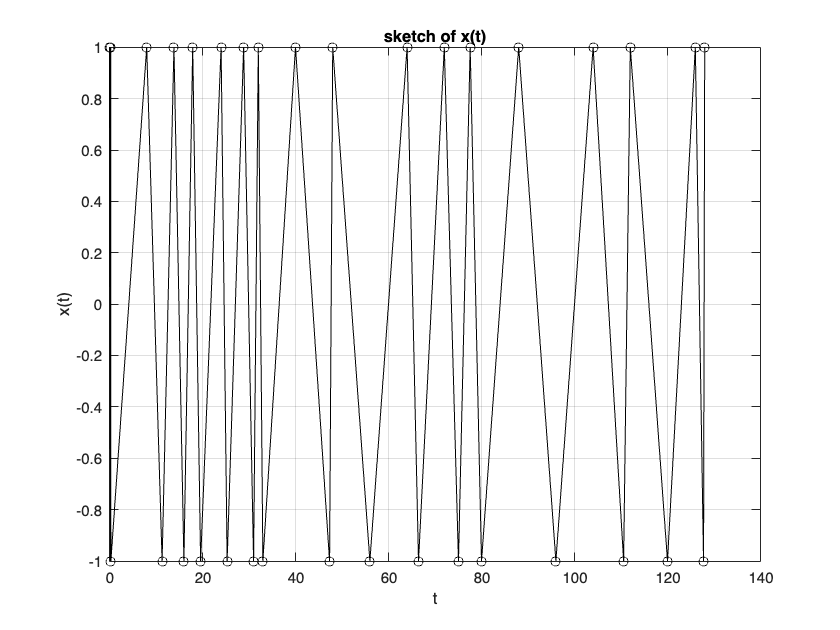

clear

% sketch of x_t
t = 0:1/64:128;
x_t = cos(pi*t.^2/64);
tol = 1e-5;

a_k = t(abs(x_t - 1) < tol);
b_k = t(abs(x_t + 1) < tol);

t_plot = sort([a_k b_k]);
t_plot(2:11) = [];

n = 0:length(t_plot)-1;
x_plot = (-1).^(n);

plot(t_plot, x_plot, 'k-o');
xlabel('t');
ylabel('x(t)');
title('sketch of x(t)');
grid on;

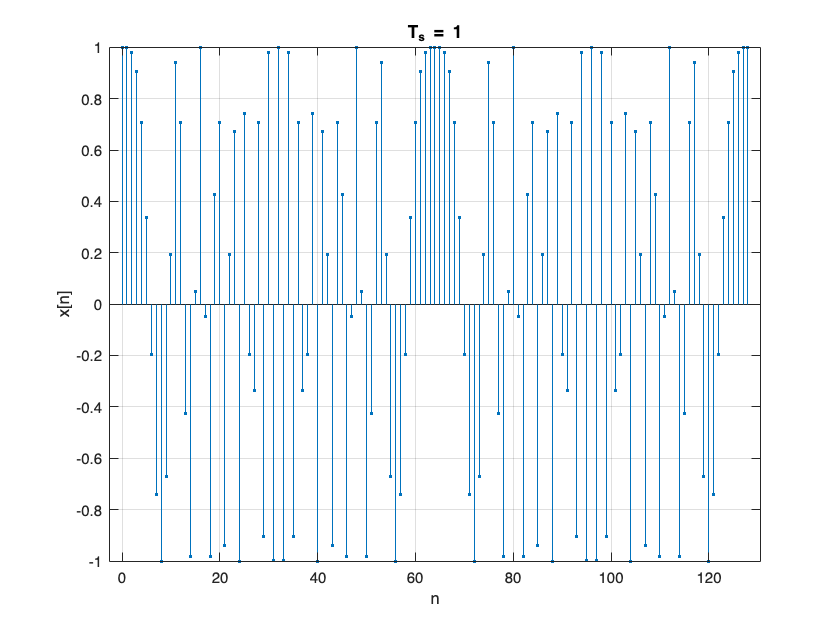

clear

T_s = 1;
n = 0:128/T_s;
x_n = cos(pi * T_s^2 * n.^2 / 64);

stem(n, x_n, '.', 'filled');
xlabel('n');
ylabel('x[n]');
title('T_s = 1');
grid on;

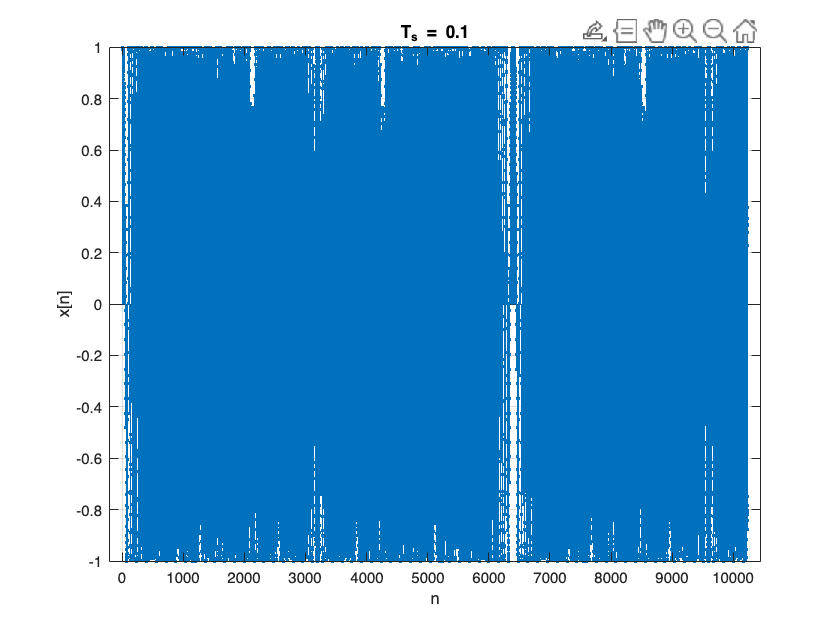

clear

T_s = 0.1;
n = 0:1024/T_s;
x_n = cos(pi * T_s^2 * n.^2 / 64);

stem(n, x_n, '.', 'filled');
xlabel('n');
ylabel('x[n]');
title('T_s = 0.1');
grid on;